# Edge Detection Example

This example shows the implementation of an edge detector for a image processing pipeline.

## Matlab Implementation

The Matlab implementation uses convolution filters using Sobel Filter values to detect the horizontal and vertical edges.

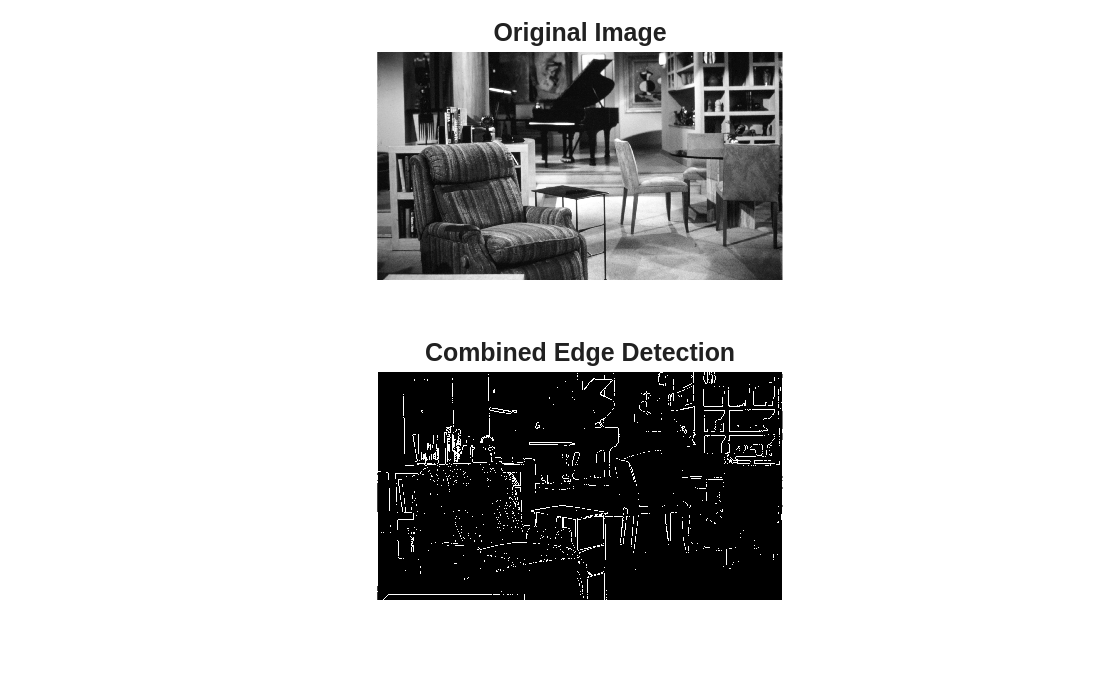

% Read and prepare the image
input_image = imread('frasier.jpg');

% Convert to grayscale if needed
if size(input_image, 3) == 3
    input_image_gray = rgb2gray(input_image);
else
    input_image_gray = input_image;
end

% Convert to double for processing
input_image_gray = double(input_image_gray);

% Define Sobel filter kernels
sobel_kx = [-1 0 1; -2 0 2; -1 0 1];  % Horizontal edges
sobel_ky = [-1 -2 -1; 0 0 0; 1 2 1];  % Vertical edges

% Threshold controls the edge sensitivity (0 - 1)
threshold = 0.1;

[edge_bin] = edge_detect(input_image_gray,sobel_kx,sobel_ky,threshold);

% Display results
figure;
subplot(2, 1, 1);
imshow(uint8(input_image_gray));
title('Original Image');

subplot(2, 1, 2);
imshow(edge_bin);
title('Combined Edge Detection');

## Simulink Implementation

We will now convert the Matlab to Simulink so we can generate HDL Code